GWA_st.name='GWA'; 
GWA_st.lat=33.2204;
GWA_st.lon=-108.235;
GWA_st.alt=1775;


GWA_rd=read_betsy('GWA_head',GWA_st.name);

datevec(GWA_rd.Time(1))

ans =         1994           4           2           0           0           0

datevec(GWA_rd.Time(end))

ans =         2004           1           1           0           0           0

prctile(GWA_rd.U_S,[5 50 95])

ans =    15.4850   48.2600   86.9845

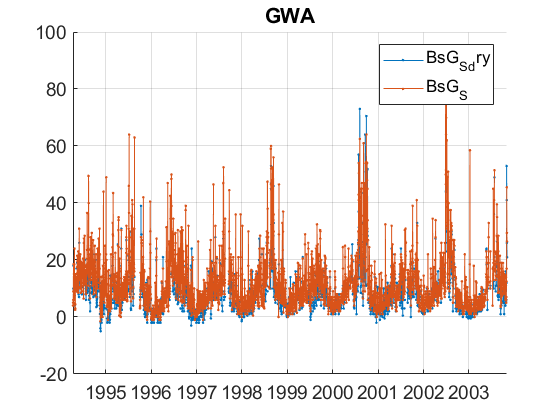

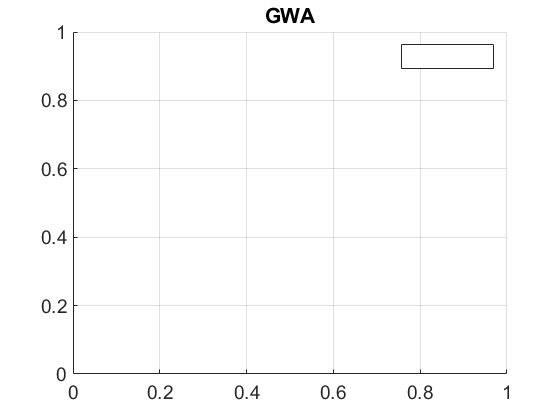

plotFigControl(GWA_rd,GWA_st.name);

% 1 size cut, ok
% sc: ok, max in summer, few negatives



% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE3=[467;530;660]*ones(1,4);
% % lambdaAE7=[370 470 520 590 660 880 950];
% % GWA_cal=compute_exp_SSA(GWA_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(GWA_cal,GWA_st.name);

%Questions:
%problems:
% holes from July 2011 to April 2012 and from April 2013 to november 2013: real holes of databank problems



GWA_t=timetable(GWA_rd.Time);
% begin at the beginning of a year: 1995
% end: 2003 --> 9y too short